## Tetrahedron Testing

## Instructions

This is my main file I use to generate curve parameters for different gaits. Make sure this file stays with fwdKin.m, invKin.m, gaitCalc.m, circle.mlx, plotTetrahedron.mlx, Rx.mlx, Ry.mlx, Rz.mlx

- Set generateAnimation to 1 if you want to have animations.  

- Set makeGraphs to 1 if you want to save all the output graphs for X Y positions and curve parameters as files in the working directory.

- Set writeCurveParameterFiles to 1 if you want to save the curve parameters into named files 

- Check the value for n to make sure you are generating the number of "frames" you want.

- Check values for r, x0, y0, and zeta to customize your fundamental shape.

- Set del to your desired delay between .gif frames so they are a nice speed.

- Change the Gait array to set which Gaits you want to generate curve parameters for.

The origin of the robot is located in the base of the top module. Other legs are named as one, two, three in clockwise direction. 

Here is a picture reference to help:

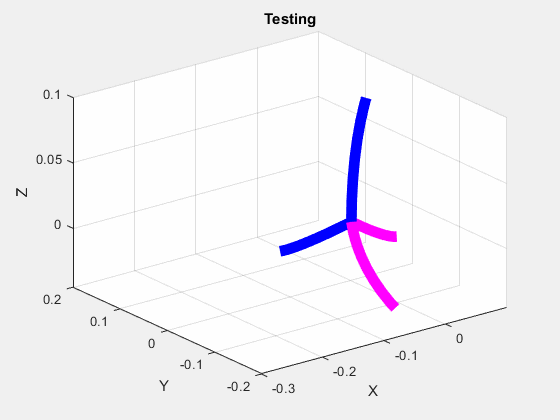

generateCoM = 0;
generateAnimation = 1;
makeGraphs = 0;
writeCurveParameterFiles = 0;

close all;

animationResolution = 10; % Number of points to animate a single arm. I suggest leaving this at 10, it gives good results

n=100; % Number of points to calculate for one period.

T = n; % Period length

These values dictate the fundamental shape for leg motion, shown here. 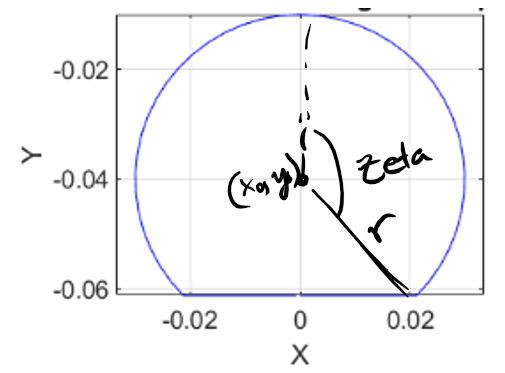

r = 0.04 ; % In meters

x0 = 0; % In meters
y0 = -0.0000000001; % In meters

zeta = 4*pi/4 ; % 3*pi/4;

ground = sin(pi/2-zeta)*r + y0;

del = 0.08; % Set the time between frames in the generated gifs. Units in seconds

topCurveParams = zeros(2,n);
oneCurveParams = zeros(2,n);
twoCurveParams = zeros(2,n);
threeCurveParams = zeros(2,n);

topLegXYZ = zeros(2,n);
oneLegXY = zeros(2,n);
twoLegXY = zeros(2,n);
threeLegXY = zeros(2,n);

originalTopLegXY = zeros(2,n);
originalOneLegXY = zeros(2,n);
originalTwoLegXY = zeros(2,n);
originalThreeLegXY = zeros(2,n);

times = linspace(1,n);
% for gait = [1 2 3 4] %Expected gait patterns
for gait = 1 % Change this to set which Gaits you are testing
    if ~exist(strcat(pwd,"\generatedGifs\",string(gait),"Gait\"), 'dir')
        mkdir(strcat(pwd,"\generatedGifs\",string(gait),"Gait\"))
    end
    if ~exist(strcat(pwd,"\generatedCSVs\",string(gait),"Gait\"), 'dir')
        mkdir(strcat(pwd,"\generatedCSVs\",string(gait),"Gait\"))
    end
    if ~exist(strcat(pwd,"\generatedGraphs\",string(gait),"Gait\"), 'dir')
        mkdir(strcat(pwd,"\generatedGraphs\",string(gait),"Gait\"))
    end
    % for turnDirection = ["Straight", "Left", "Right", "Clockwise", "Anticlockwise"]
    %for turnDirection = "Left" % Change this to set how many different types of turns you want to process
    dataFileMatrix = zeros(n, 9); % This will get filled up and written to a file for every (Gait, turnDirection) combination.
    
    for i = 1:n
        gaitInput = [i T x0 y0 r zeta];
        turnRadius = 0.3; % Turn radius must be bigger than the horizontal length from the body to a foot
        % I assume a horiontal length of 0.1
        % meters, (or (2/3)*L)
        
        originalTopLegXY(:,i) = gaitCalc(gaitInput, 0, gait);
        originalOneLegXY(:,i) = gaitCalc(gaitInput, 1, gait);
        originalTwoLegXY(:,i) = gaitCalc(gaitInput, 2, gait);
        originalThreeLegXY(:,i) = gaitCalc(gaitInput, 3, gait);
        
        
        topCurveParams(:,i) = invKin(originalTopLegXY(:,i));
        oneCurveParams(:,i) = invKin(originalOneLegXY(:,i));
        twoCurveParams(:,i) = invKin(originalTwoLegXY(:,i));
        threeCurveParams(:,i) = invKin(originalThreeLegXY(:,i));
        
        dataFileMatrix(i,:) = [i,topCurveParams(:,i).',oneCurveParams(:,i).',twoCurveParams(:,i).',threeCurveParams(:,i).'];
        
        
        temp = fwdKin(topCurveParams(:,i),1);
        topLegXY(:,i) = temp(1:2,:);
        temp = fwdKin(oneCurveParams(:,i),1);
        oneLegXY(:,i) = temp(1:2,:);
        temp = fwdKin(twoCurveParams(:,i),1);
        twoLegXY(:,i) = temp(1:2,:);
        temp = fwdKin(threeCurveParams(:,i),1);
        threeLegXY(:,i) = temp(1:2,:);
        
        % the gif
        if generateAnimation == 1
            curveParams = [topCurveParams(:,i) oneCurveParams(:,i) twoCurveParams(:,i) threeCurveParams(:,i)];
            myFigure = plotTetrahedron(curveParams, strcat("Testing"), ground,"Standard");
            frame = getframe(myFigure);
            
            im = frame2im(frame);
            [imind,cm] = rgb2ind(im,256);
            % Write to the GIF File
            if i == 1
                imwrite(imind,cm,strcat(pwd,"\generatedGifs\",string(gait),"Gait\",string(gait),'Gait_Standard_view_','_Animation.gif'),'gif', 'Loopcount',inf,'DelayTime',del);
            else
                imwrite(imind,cm,strcat(pwd,"\generatedGifs\",string(gait),"Gait\",string(gait),'Gait_Standard_view_','_Animation.gif'),'gif','WriteMode','append','DelayTime',del);
            end
            clf('reset')
            
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            
            myFigure = plotTetrahedron(curveParams, strcat(string(gait)," Gait XY View: "), ground, "XY");
            frame = getframe(myFigure);
            im = frame2im(frame);
            [imind,cm] = rgb2ind(im,256);
            % Write to the GIF File
            if i == 1
                imwrite(imind,cm,strcat(pwd,"\generatedGifs\",string(gait),"Gait\",string(gait),'Gait_XY_view_','_Animation.gif'),'gif', 'Loopcount',inf,'DelayTime',del);
            else
                imwrite(imind,cm,strcat(pwd,"\generatedGifs\",string(gait),"Gait\",string(gait),'Gait_XY_view_','_Animation.gif'),'gif','WriteMode','append','DelayTime',del);
            end
            clf('reset')
            
            myFigure = plotTetrahedron(curveParams,strcat(string(gait),"Gait XZ View: "), ground, "XZ");
            frame = getframe(myFigure);
            im = frame2im(frame);
            [imind,cm] = rgb2ind(im,256);
            % Write to the GIF File
            if i == 1
                imwrite(imind,cm,strcat(pwd,"\generatedGifs\",string(gait),"Gait\",string(gait),'Gait_XZ_view_','_Animation.gif'),'gif', 'Loopcount',inf,'DelayTime',del);
            else
                imwrite(imind,cm,strcat(pwd,"\generatedGifs\",string(gait),"Gait\",string(gait),'Gait_XZ_view_','_Animation.gif'),'gif','WriteMode','append','DelayTime',del);
            end
            clf('reset')
            
            myFigure = plotTetrahedron(curveParams,strcat(string(gait),"Gait YZ View: "), ground, "YZ");
            frame = getframe(myFigure);
            im = frame2im(frame);
            [imind,cm] = rgb2ind(im,256);
            % Write to the GIF File
            if i == 1
                imwrite(imind,cm,strcat(pwd,"\generatedGifs\",string(gait),"Gait\",string(gait),'Gait_YZ_view_','_Animation.gif'),'gif', 'Loopcount',inf,'DelayTime',del);
            else
                imwrite(imind,cm,strcat(pwd,"\generatedGifs\",string(gait),"Gait\",string(gait),'Gait_YZ_view_','_Animation.gif'),'gif','WriteMode','append','DelayTime',del);
            end
            clf('reset')
            
            
            %%%%%%%%%%%%%%%%%%%
            
            
            
        end
    end
    
    % The curve parameters data file is a csv file organized by
    %(time, topTheta, topPhi, oneTheta, onePhi, twoTheta, twoPhi, threeTheta, threePhi)
    if writeCurveParameterFiles == 1
        if gait == 0
            writematrix(dataFileMatrix, strcat(pwd,"\generatedCSVs\",string(gait),"Gait\","Trot","CurveParams.csv"))
        else
            writematrix(dataFileMatrix, strcat(pwd,"\generatedCSVs\",string(gait),"Gait\",string(gait),"Gait","curveParams.csv"))
        end
    end
    
    % All these graphs are saved into separate image files
    if makeGraphs == 1
        close all force
        n=100;
        f=0.25;T=1/f;N=3;r=0.018;
        t=linspace(0,T,n+1)';t(end)=[];
        times=t;
        
        figure(2);
        subplot(2,1,1);%tiledlayout(2,1);
        %nexttile;
        plot(times, topLegXY(1,:), 'r','LineWidth',2); hold on;
        plot(times, oneLegXY(1,:), 'b','LineWidth',2); hold on;
        plot(times, twoLegXY(1,:), 'g','LineWidth',2);hold on;
        plot(times, threeLegXY(1,:), 'm','LineWidth',2); hold on;
        grid;
        %title(strcat(string(gait)," Gait ",turnDirection," Gait Time vs Top Position"));
        %title("Gait Time vs Leg Positions");
        xlabel("Time (s)");
        ylabel("X (m)");
        fig2 = gca;
        set(gca,'FontSize',20); set(gca,'FontWeight','bold');
        lgd = legend('Leg1','Leg2','Leg3','Leg4');%lgd.NumColumns = 3;
        lgd.FontSize = 10;
        xticks([0:1:4]);
        yticks([-0.04:0.04:0.04]);
        %hold off;
        
        
        subplot(2,1,2);
        plot(times, topLegXY(2,:), 'r','LineWidth',2); hold on;
        plot(times, oneLegXY(2,:), 'b','LineWidth',2);hold on;
        %plot(times, twoLegXY(2,:), 'g','LineWidth',2);hold on;
        %plot(times, threeLegXY(2,:), 'm','LineWidth',2);hold on;
        grid;
        set(gca,'FontSize',20); set(gca,'FontWeight','bold');
        lgd = legend('Leg1','Leg2','Leg3','Leg4');%lgd.NumColumns = 3;
        lgd.FontSize = 10;
        xlabel("Time (s)");
        ylabel("Y (m)");
        xticks([0:1:4]);
        yticks([-0.04:0.04:0.04]);
        hold off;
        
        %figure(3);
        %subplot(2,1,1); %tiledlayout(2,1);
        %nexttile;
        %plot(times, oneLegXY(1,:), 'red');
        %         grid;
        %         title(strcat(string(gait)," Gait ",turnDirection," Gait Time vs Front Left Position"));
        %         xlabel("Time");
        %         ylabel("X Position");
        %         fig3 = gca;
        
        
        %nexttile;
        %         subplot(2,1,2);
        %         plot(times, oneLegXY(2,:), 'b');
        %         grid;
        %         xlabel("Time");
        %         ylabel("Y Position");
        
        %         figure(4);
        %         subplot(2,1,1);%tiledlayout(2,1);
        %         %nexttile;
        %         plot(times, twoLegXY(1,:), 'red');
        %         grid;
        %         title(strcat(string(gait)," Gait ",turnDirection," Gait Time vs Back Left Position"));
        %         xlabel("Time");
        %         ylabel("X Position");
        %         fig4 = gca;
        
        
        %         %nexttile;
        %         subplot(2,1,2);
        %         plot(times, twoLegXY(2,:), 'b');
        %         grid;
        %         xlabel("Time");
        %         ylabel("Y Position");
        
        %         figure(5);
        %         subplot(2,1,1); %tiledlayout(2,1);
        %         %nexttile;
        %         plot(times, threeLegXY(1,:), 'red');
        %         grid;
        %         title(strcat(string(gait)," Gait ",turnDirection," Gait Time vs Back Right Position"));
        %         xlabel("Time");
        %         ylabel("X Position");
        %         fig5 = gca;
        
        
        %         %nexttile;
        %         subplot(2,1,2);
        %         plot(times, threeLegXY(2,:), 'b');
        %         grid;
        %         xlabel("Time");
        %         ylabel("Y Position");
        
        
        figure(6);
        subplot(2,1,1);
        plot(t, topCurveParams(1,:), 'r','LineWidth',2); hold on;
        plot(t, oneCurveParams(1,:), 'b','LineWidth',2); hold on;
        plot(t, twoCurveParams(1,:), 'g','LineWidth',2); hold on;
        plot(t, threeCurveParams(1,:), 'm','LineWidth',2); hold on;
        grid;
        %title(strcat(string(gait)," Gait ",turnDirection," Gait Time vs top Curve Parameter"));
        %title( "Gait Time vs Curve Parameters");
        xlabel("Time (s)");
        ylabel("Theta [rad]");
        fig6 = gca;
        set(gca,'FontSize',18); set(gca,'FontWeight','bold');
        lgd = legend('Leg1','Leg2','Leg3','Leg4');%lgd.NumColumns = 3;
        lgd.FontSize = 9;
        
        subplot(2,1,2);
        plot(t, topCurveParams(2,:), 'r','LineWidth',2); hold on;
        plot(t, oneCurveParams(2,:), 'b','LineWidth',2); hold on;
        plot(t, twoCurveParams(2,:), 'g','LineWidth',2); hold on;
        plot(t, threeCurveParams(2,:), 'm','LineWidth',2); hold on;
        grid;
        xlabel("Time (s)");
        ylabel("Phi [rad]");
        set(gca,'FontSize',18); %set(gca,'FontWeight','bold');
        lgd = legend('Leg1','Leg2','Leg3','Leg4');%lgd.NumColumns = 3;
        lgd.FontSize = 9;
        hold off;
        
        %         figure(7);
        %         subplot(2,1,1); %nexttile;
        %         plot(times, oneCurveParams(1,:));
        %         grid;
        %         title(strcat(string(gait)," Gait ",turnDirection," Gait Time vs one Curve Parameter"));
        %         xlabel("Time");
        %         ylabel("Theta [radians]");
        %         fig7 = gca;
        
        %         subplot(2,1,2);%nexttile;
        %         plot(times, oneCurveParams(2,:));
        %         grid;
        %         xlabel("Time");
        %         ylabel("Phi [radians]");
        %
        %         figure(8);
        %         subplot(2,1,1);%nexttile;
        %         plot(times, twoCurveParams(1,:));
        %         grid;
        %         title(strcat(string(gait)," Gait ",turnDirection," Gait Time vs two Curve Parameter"));
        %         xlabel("Time");
        %         ylabel("Theta [radians]");
        %         fig8 = gca;
        %
        %         subplot(2,1,2);%nexttile;
        %         plot(times, twoCurveParams(2,:));
        %         grid;
        %         xlabel("Time");
        %         ylabel("Phi [radians]");
        %
        %         figure(9);
        %         subplot(2,1,1);%nexttile;
        %         plot(times, threeCurveParams(1,:));
        %         grid;
        %         title(strcat(string(gait)," Gait ",turnDirection," Gait Time vs three Curve Parameter"));
        %         xlabel("Time");
        %         ylabel("Theta [radians]");
        %         fig9 = gca;
        %
        %         subplot(2,1,2);%nexttile;
        %         f = plot(times, threeCurveParams(2,:));
        %         grid;
        %         xlabel("Time");
        %         ylabel("Phi [radians]");
        %
        
        figure(10);
        subplot(2,1,1);
        %nexttile;
        plot(originalTopLegXY(1,:), originalTopLegXY(2,:), 'blue');
        grid;
        title(strcat(string(gait)," Gait ",turnDirection," Gait Original Shape"));
        xlabel("X");
        ylabel("Y");
        axis equal
        
        temp = zeros(3, n);
        for i = 1:n
            temp(:,i) = fwdKin(topCurveParams(:,i), 1);
        end
        subplot(2,1,2);
        plot(temp(1,:), temp(2,:), 'red');
        grid;
        title(strcat(string(gait)," Gait ",turnDirection," Gait Forward Kinematics Shape"));
        xlabel("X");
        ylabel("Y");
        axis equal;
        fig10 = gca;
        
        for fig = [fig2, fig6, fig10]
            %saveas(fig,strcat(pwd,"\generatedGraphs\",string(gait),"Gait\",fig.Title.String,".png"));
        end
    end
    %end
end